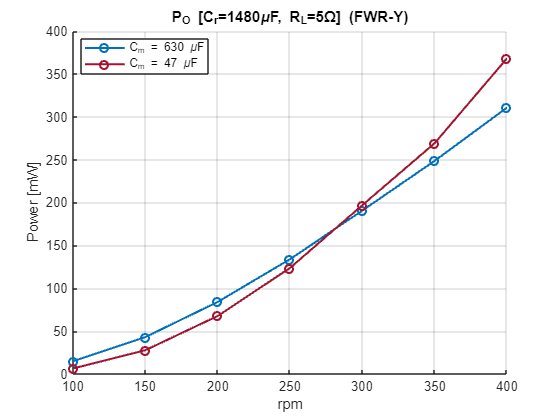


% Dati misurati (Y1_f_sweep.csv, Y2_f_sweep.csv):
% sweep di rpm per i valori fissi del condensatore di compensazione C_m dei
% due bridge FWR-Star (Y1: 7 valori, 630-47 uF; Y2: 8 valori, 730-47 uF, una
% colonna in piu' rispetto a Y1), R = 16 Ohm fisso per entrambi.
% NOTA: qui i CSV usano la virgola come separatore decimale semplice (es.
% "20,4383" = 20.4383 mW): a differenza del FWR-Delta, tutti i valori sono
% sotto le migliaia, quindi non c'e' l'ambiguita' del raggruppamento a tre
% cifre e nessuna correzione di virgola e' stata necessaria qui.
%
% Per C_m = 630 uF e C_m = 47 uF e' disponibile anche la misura reale con i
% due bridge gia' collegati in parallelo (Y_1+2_f_sweep.csv, R = 7 Ohm,
% nessun dato di Pi): il grafico di P_O combinato usa solo queste due
% colonne (misura reale), non una somma calcolata dei bridge singoli.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso

rpm_plot = [100 150 200 250 300 350 400];

C_L_plot_1 = [630 530 430 330 200 100 47]*1e-6;      % F - Cm di Y1 (7 valori)
C_L_plot_2 = [730 630 530 430 330 200 100 47]*1e-6;  % F - Cm di Y2 (8 valori, +730uF)
n_CL1 = numel(C_L_plot_1);
n_CL2 = numel(C_L_plot_2);
colors1 = lines(n_CL1);
colors2 = lines(n_CL2);


% Potenza reale misurata con i due bridge gia' in parallelo (Y_1+2_f_sweep.csv, R=7 Ohm),
% disponibile solo per C_m = 630 uF e C_m = 47 uF
Po_meas_630_mW = [47.5646  107.5265 175.4865 245.0959 312.8417 374.5425 433.3099];
Po_meas_47_mW  = [8.6523   39.4223  100.7726 199.6428 339.7354 507.3992 677.2469];

% Grafico P_O ridotto alle sole due colonne con misura reale (bridge gia'
% in parallelo, R=7 Ohm): C_m piu' grande (630uF) e C_m piu' piccolo (47uF).
figure;
hold on;
plot(rpm_plot, Po_meas_630_mW, 'o-', 'LineWidth', 1.5, 'Color', colors1(1,:));
plot(rpm_plot, Po_meas_47_mW, 'o-', 'LineWidth', 1.5, 'Color', colors1(n_CL1,:));
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=7\\Omega, misura reale] (FWR-Y)', C_r*1e6));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries_Po = {sprintf('C_m = %.0f \\muF', C_L_plot_1(1)*1e6), sprintf('C_m = %.0f \\muF', C_L_plot_1(n_CL1)*1e6)};
legend(legendEntries_Po, 'Location', 'best');

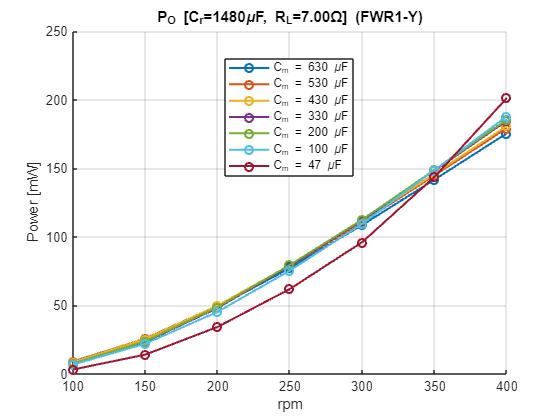

hold off;


% Sweep di frequenza dei singoli bridge Y1/Y2 (Y1_f_sweep.csv, Y2_f_sweep.csv),
% un grafico ciascuno; R = 16 Ohm fisso per entrambi. Y2 include una colonna
% in piu' (C_m = 730 uF) assente in Y1.

P_b1_mW = [ ...
     20.4383  20.3413  19.6403  18.9886  17.1955  11.1425   5.4770; ...
     45.5972  47.5442  48.3461  48.6795  47.3207  37.7849  23.5291; ...
     75.1098  78.8929  82.1210  83.8310  84.6557  79.5950  58.2643; ...
    106.4137 111.7927 116.7513 119.8528 123.3461 129.3552 109.5704; ...
    137.5399 144.1933 150.0807 153.8286 159.0900 176.8926 169.4387; ...
    167.9328 175.6944 182.9981 186.7792 194.1073 220.8320 233.4971; ...
    197.0520 205.1922 213.1411 217.5789 225.8334 258.7259 292.4727];

Pi_b1_mW = [ ...
     50.2063  49.8765  48.6481  47.6335  44.1034  32.3641  19.9382; ...
     98.5433 101.7972 103.1067 104.0445 102.7071  87.3280  62.5222; ...
    151.1722 157.9184 162.7092 165.8806 169.6790 164.6236 132.9540; ...
    204.5047 213.8729 221.5491 226.4100 235.7545 250.2065 228.1403; ...
    255.5301 266.8344 276.3488 281.9791 295.4672 328.8214 331.9851; ...
    306.5823 318.7434 329.8994 335.9534 352.1394 400.2882 439.0673; ...
    353.0103 365.8732 378.0482 383.9068 402.2399 459.5935 533.6013];

P_b2_mW = [ ...
     21.4933  21.9748  21.9212  19.5186  17.8702  13.2646   8.6146   3.0876; ...
     46.5886  48.6828  50.0708  50.4276  49.1226  41.1912  32.3378  15.6640; ...
     75.7569  79.6653  82.0253  80.9954  87.4473  80.6787  76.0491  41.7869; ...
    106.5534 111.8197 115.1985 120.9914 126.4580 128.7975 135.0127  87.4815; ...
    137.4932 142.9692 147.0912 154.5436 162.0815 174.4294 194.0980 157.2594; ...
    168.2422 174.0066 178.4166 186.7309 194.4971 214.4378 245.4987 244.6030; ...
    196.8564 202.8492 207.2167 216.2517 225.2527 249.2709 284.9353 327.5689];

Pi_b2_mW = [ ...
     52.6648  53.2217  53.2770  49.3575  46.1240  36.3925  26.6199  13.1185; ...
    101.2150 103.3652 105.9618 108.3980 107.2826  93.6741  77.1120  45.7419; ...
    153.6106 157.4284 161.6486 169.5832 176.4588 171.0897 160.3235 102.2117; ...
    206.6535 211.2025 216.8614 229.8964 243.3239 257.8760 265.8342 193.1710; ...
    257.4723 262.0474 268.6492 284.6733 302.9704 336.7620 367.4757 324.6109; ...
    306.5142 311.2468 318.2081 335.9374 357.6603 403.3621 451.9522 483.1422; ...
    352.2296 356.3697 363.3497 382.2160 406.1777 457.9835 515.5050 630.4196];

eta_b1 = P_b1_mW ./ Pi_b1_mW;
eta_b2 = P_b2_mW ./ Pi_b2_mW;

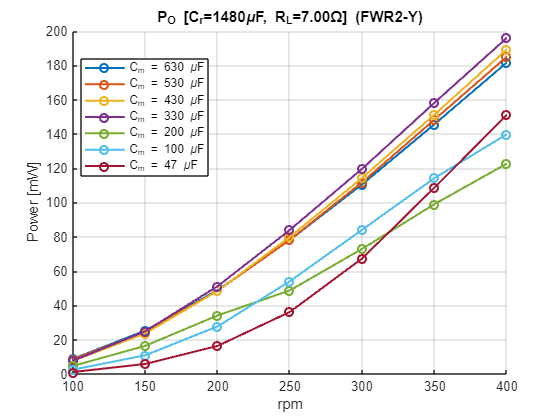


figure;
hold on;
for k = 1:n_CL1
    plot(rpm_plot, P_b1_mW(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors1(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=16\\Omega] (FWR1-Y)', C_r*1e6));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL1);
for k = 1:n_CL1
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot_1(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

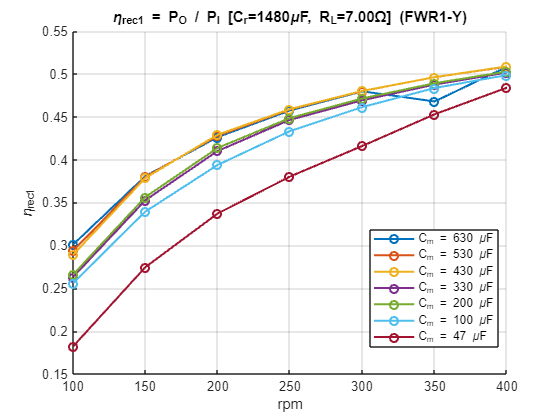


figure;
hold on;
for k = 1:n_CL2
    plot(rpm_plot, P_b2_mW(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors2(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=16\\Omega] (FWR2-Y)', C_r*1e6));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL2);
for k = 1:n_CL2
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot_2(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;


% Efficienza dei singoli bridge Y1/Y2 (eta_rec = P_O/P_I), stessa disposizione
% righe/colonne di P_b1_mW/P_b2_mW.

figure;
hold on;
for k = 1:n_CL1
    plot(rpm_plot, eta_b1(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors1(k,:));
end
grid on;
title(sprintf('\\eta_{rec1} = P_O / P_I [C_r=%.0f\\muF, R_L=16\\Omega] (FWR1-Y)', C_r*1e6));
xlabel('rpm');
ylabel('\eta_{rec1}');
legendEntries = cell(1, n_CL1);
for k = 1:n_CL1
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot_1(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

figure;
hold on;
for k = 1:n_CL2
    plot(rpm_plot, eta_b2(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors2(k,:));
end
grid on;
title(sprintf('\\eta_{rec2} = P_O / P_I [C_r=%.0f\\muF, R_L=16\\Omega] (FWR2-Y)', C_r*1e6));

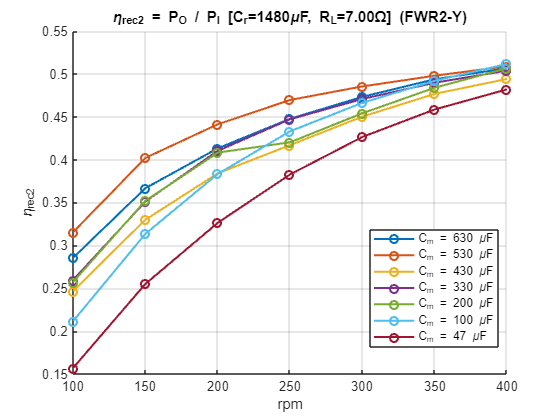

xlabel('rpm');
ylabel('\eta_{rec2}');
legendEntries = cell(1, n_CL2);
for k = 1:n_CL2
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot_2(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;